% Perform PCA on handwritten images of the digit 3 
% taken from the US Postal Service database.

% access the images

load threes -ascii

colormap('gray')
i = 10

i = 10

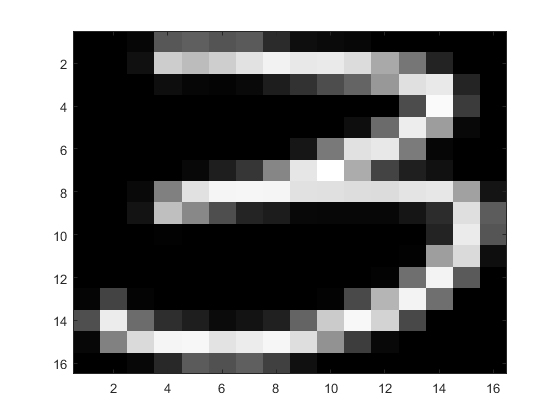

imagesc(reshape(threes(i,:),16,16),[0,1])

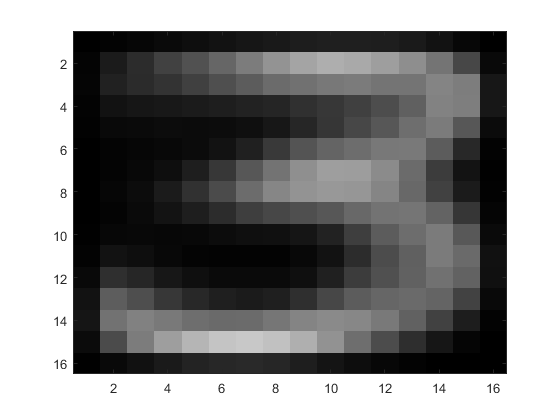


% Compute the mean 3 and display it.
mean3 = mean(threes);
threes_constructed = threes - mean3;
imagesc(reshape(mean3,16,16),[0,1])

% Compute the covariance matrix of the whole dataset of 3s (note that the Matlab function cov subtracts the mean automatically,
% subtracting it beforehand is not incorrect however).
threes_cov = cov(threes);

% Compute the eigenvalues and eigenvectors of this covariance
% matrix. Plot the eigenvalues (plot(diag(D) where D is the diagonal matrix of eigenvalues).

[V,D] = eig(threes_cov);
%plot(diag(D));
eigenvalues = flipud(diag(D));
plot(eigenvalues);

xlabel('i') 
ylabel('i-th eigenvalue')


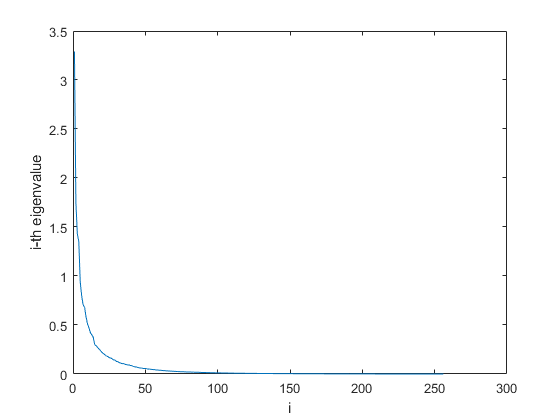

% reconstruct the image using q principal components
eigenValues = diag(D);
[eigenValues,ind] = sort(eigenValues,"descend");

% create the projection matrix ET
q = 4;
QLargestEigenValues = eigenValues(1:q);
ET = V(:,ind(1:q));
ET = ET';

% compress the dataset
threes_reduced = ET * (threes_constructed)';
threes_reduced = threes_reduced';
% reconstruct the dataset 
threes_reconstructed = threes_reduced * ET;
threes_reconstructed = threes_reconstructed + mean3;

% plot some reconstructed images
colormap('gray')

i = 10

i = 10

text = ['Reconstructed image with ',num2str(q),' principle components'];
disp(text)

Reconstructed image with 4 principle components


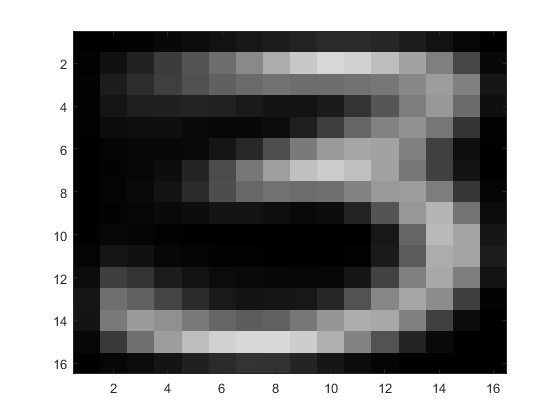

imagesc(reshape(threes_reconstructed(i,:),16,16),[0,1])

% measure the reconstruction error
RMS = (sqrt(mean(mean((threes_reconstructed-threes).^2))))

RMS = 0.2213


% % reconstruct the image using q principal components
% eigenValues = diag(D);
% [eigenValues,ind] = sort(eigenValues,"descend");
% 
% % create the projection matrix ET
% q = 256;
% QLargestEigenValues = eigenValues(1:q);
% ET = V(:,ind(1:q));
% ET = ET';
% 
% % compress the dataset
% threes_reduced = ET * (threes)';
% threes_reduced = threes_reduced';
% % reconstruct the dataset 
% threes_reconstructed = threes_reduced * ET;
% threes_reconstructed = threes_reconstructed + mean3;
% 
% % plot some reconstructed images
% colormap('gray')
% i = 100
% imagesc(reshape(threes_reconstructed(i,:),16,16),[0,1])
% % measure the reconstruction error
% RMS = (sqrt(mean(mean((threes_reconstructed-threes).^2))));

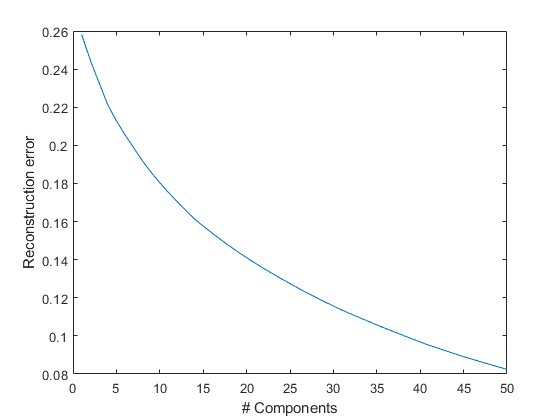

% plot the reconstruction error as a function of q

q = 50;
reconstruction_error = zeros(1,q);
for i = 1:q
    reconstruction_error(i) = mypca(threes,mean3,V,D,i);
end

plot(reconstruction_error)
xlabel('# Components') 
ylabel('Reconstruction error')

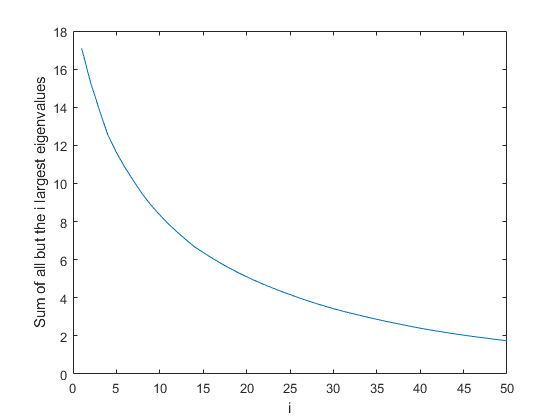

% Use the Matlab function cumsum to create a vector whose i-th element is the sum of all but the i largest eigenvalues for
% i = 1 : 256. Compare the first 50 elements of this vector to the vector of reconstruction errors calculated previously.
eigenValues = diag(D);
[eigenValues,ind] = sort(eigenValues,"descend");

sum_largest_eigenValues = cumsum(eigenValues);

% for i = 1:256
%     sum_largest_eigenValues(i) = sum_largest_eigenValues(i) - eigenValues(i);
% end

sum_eigenvalues = sum(eigenValues);

sum_largest_eigenValues = sum_eigenvalues - sum_largest_eigenValues;

plot(sum_largest_eigenValues(1:50))
xlabel('i') 
ylabel('Sum of all but the i largest eigenvalues')